# Homework 6

**Name:** YOUR NAME HERE

**Last modified: **June 29, 2022

clear, clc

## Problem #1 - Eigenvalues

**SETUP FOR PROBLEM**

A = [-10 9;-6 5];

**a) Eigenvalues "by hand"**


$$\begin{array}{l}
\left|\lambda \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
-10 & 9\\
-6 & 5
\end{array}\right\rbrack \right|=0\\
\\
\left|\left\lbrack \begin{array}{cc}
\lambda +10 & -9\\
6 & \lambda -5
\end{array}\right\rbrack \right|=0\\
\\
\left(\lambda +10\right)\bullet \left(\lambda -5\right)-\left(-9\right)\bullet \left(6\right)=0\\
\\
\lambda^2 +5\lambda -50+54=0\\
\\
\lambda^2 +5\lambda +4=0\\
\\
\left(\lambda +4\right)\left(\lambda +1\right)=0\\
\\
\lambda_1 =-4,\;{\;\lambda }_2 =-1
\end{array}$$


**b) Eigenvectors "by hand"**


$$\begin{array}{l}
\left\lbrack \left\lbrack \begin{array}{cc}
-10 & 9\\
-6 & 5
\end{array}\right\rbrack -\lambda_i \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \right\rbrack V_i =0\\
\left\lbrack \left\lbrack \begin{array}{cc}
-10 & 9\\
-6 & 5
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
-4 & 0\\
0 & -4
\end{array}\right\rbrack \right\rbrack V_1 =0\\
\left\lbrack \begin{array}{cc}
-6 & 9\\
-6 & 9
\end{array}\right\rbrack V_1 =0\\
V_1 =\left\lbrack \begin{array}{c}
9\\
6
\end{array}\right\rbrack \\
\left\lbrack \left\lbrack \begin{array}{cc}
-10 & 9\\
-6 & 5
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & -1
\end{array}\right\rbrack \right\rbrack V_2 =0\\
\left\lbrack \begin{array}{cc}
-9 & 9\\
-6 & 6
\end{array}\right\rbrack V_2 =0\\
V_2 =\left\lbrack \begin{array}{c}
9\\
9
\end{array}\right\rbrack 
\end{array}$$


Vh = [9 9;
      6 9];
Vh(:,1) = Vh(:,1).*-0.092450032704205;%scalar multiple
Vh(:,2) = Vh(:,2).*-0.078567420131839;%scalar multiple


**c) Calculate eigenvalues and eigenvectors using eig**

[Vm, E] = eig(A);

**d) Show eigenvalues and eigenvalues from parts a-c are same**

fprintf('The eigenvectors from MATLAB are [%d; %d] and [%d; %d]\nThe eigenvectors by hand are [%d; %d] and [%d; %d]\nThe vectors are scalar multiples of echother',Vm(1),Vm(2),Vm(3),Vm(4),Vh(1),Vh(2),Vh(3),Vh(4))

The eigenvectors from MATLAB are [-8.320503e-01; -5.547002e-01] and [-7.071068e-01; -7.071068e-01]
The eigenvectors by hand are [-8.320503e-01; -5.547002e-01] and [-7.071068e-01; -7.071068e-01]
The vectors are scalar multiples of echother

## Problem #2 - Differentiation

**SETUP FOR PROBLEM**

f = @(t) -8.7.*exp(-3.*t).*sin(-5.*t);
tVal = 0:0.25:5;
fVal = f(tVal);

**a) Plot the function**

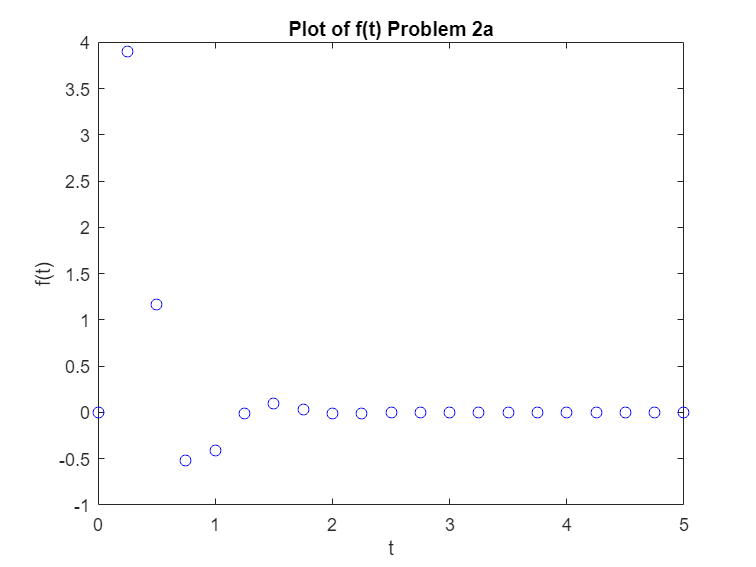

plot(tVal,fVal,'bo')
xlabel 't'
ylabel 'f(t)'
title 'Plot of f(t) Problem 2a'

**b) Calculate the derivative analytically using symbolic toolbox**

syms t
fu(t) = -8.7.*exp(-3.*t).*sin(-5.*t);
dfdt = diff(fu)

$$dfdt(t) = \frac{87\,\cos\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{2}-\frac{261\,\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{10}$$

**c) Calculate using diff**

dfDiff = diff(fVal)./diff(tVal);
tDiff = (tVal(1:end-1)+tVal(2:end))/2;

**d) Calculate using gradient**

dfGrad = gradient(fVal,tVal);

**e) Plot the derivatives from b-d**

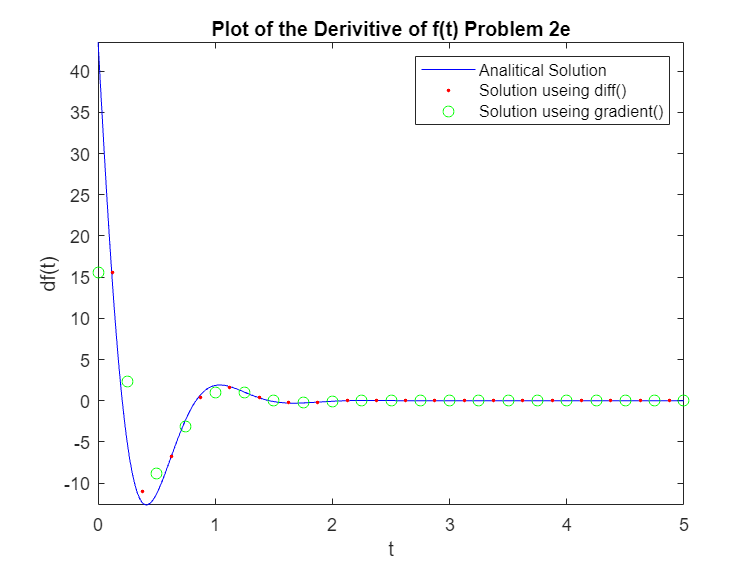

clf
fplot(dfdt,[0 5],'b')
hold on;
plot(tDiff,dfDiff,'r.',tVal,dfGrad,'go')
xlabel 't'
ylabel 'df(t)'
title 'Plot of the Derivitive of f(t) Problem 2e'
legend('Analitical Solution','Solution useing diff()','Solution useing gradient()')

## Problem #3 - Boundary value problem #1

**SETUP FOR PROBLEM**

dTdx = @(x,T) [T(2);-T(2)+5*x];
dx = 0.3;
x0 = 4;
xf = 6.4;
t0 = 500;
tf = 1100;

**a) Using shooting method**

z1 = 600;
[x1, t1] = ode45(dTdx, [x0 xf], [t0 z1]);
t1end = t1(end,1);

z2 = 6000;
[x2, t2] = ode45(dTdx, [x0 xf], [t0 z2]);
t2end = t2(end,1);

zactual = z1 + (z2 - z1)/(t2end - t1end)*(tf-t1end);
[~,Ts] = ode45(dTdx, [x0 xf], [t0 zactual]);

fprintf('guess 1: 600  %f\nguess 2: 6000 %f\nfinal value: %f',t1end,t2end,zactual)

guess 1: 600  1082.329959
guess 2: 6000 5992.452663
final value: 619.432960

**b) Using finite difference approach**

c1 = 1.7;
c2 = -4;
c3 = 2.3;

A = [c2 c3 0  0  0  0  0;
     c1 c2 c3 0  0  0  0;
     0  c1 c2 c3 0  0  0;
     0  0  c1 c2 c3 0  0;
     0  0  0  c1 c2 c3 0;
     0  0  0  0  c1 c2 c3;
     0  0  0  0  0  c1 c2;];

b = [0.9*4.3-c1*t0;
     0.9*4.6;
     0.9*4.9;
     0.9*5.2;
     0.9*5.5;
     0.9*5.8;
     0.9*6.1-c3*tf;];

Tl = A\b;
xVal = x0:dx:xf;
tVal = [t0;Tl;tf];
fprintf('x (m)    T (°R)\n------ --------\n  %.2f   %.2f\n  %.2f   %.2f\n  %.2f   %.2f\n  %.2f   %.2f\n  %.2f   %.2f\n  %.2f  %.2f\n  %.2f  %.2f\n  %.2f  %.2f\n  %.2f  %.2f',xVal(1),tVal(1),xVal(2),tVal(2),xVal(3),tVal(3),xVal(4),tVal(4),xVal(5),tVal(5),xVal(6),tVal(6),xVal(7),tVal(7),xVal(8),tVal(8),xVal(9),tVal(9))

x (m)    T (°R)
------ --------
  4.00   500.00
  4.30   662.12
  4.60   783.63
  4.90   875.24
  5.20   944.87
  5.50  998.37
  5.80  1040.07
  6.10  1073.16
  6.40  1100.00

**c) Plot**

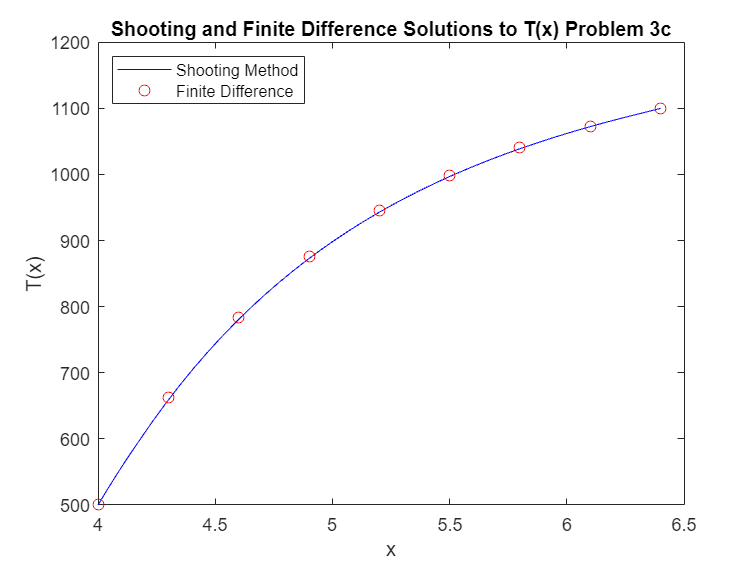

clf
plot(x1, Ts(:,1), 'b',xVal,tVal,'ro')
xlabel 'x'
ylabel 'T(x)'
title 'Shooting and Finite Difference Solutions to T(x) Problem 3c'
legend('Shooting Method','Finite Difference','Location','northwest')

## Problem #4 - Boundary value problem #2

**SETUP FOR PROBLEM**

x0 = 2;
xf = 3;
y0 = 3;
yf = 11.1;
dx = 0.2;
xfinite = x0:dx:xf;
n = length(xfinite);
yfinite = linspace(y0,yf,n);

**a) Using shooting method**

za = fzero(@shootingRes, 30, [], x0, xf, y0, yf)

za = 33.5440

[x,y] = ode45(@dydxNonlinear, [x0 xf], [y0, za], []);

**b) Using finite difference approach**



ea = 100;
itercount = 0;
while ea >= 0.09
    yold = yfinite;
    yfinite = yiter(yfinite, dx);
    ea = max(abs((yfinite-yold)./yfinite)*100);
    itercount = itercount + 1;

end
fprintf('   x       y\n---- -------\n%.2f  %.4f\n%.2f  %.4f\n%.2f %.4f\n%.2f %.4f\n%.2f %.4f\n%.2f %.4f',xfinite(1),yfinite(1),xfinite(2),yfinite(2),xfinite(3),yfinite(3),xfinite(4),yfinite(4),xfinite(5),yfinite(5),xfinite(6),yfinite(6))

   x       y
---- -------
2.00  3.0000
2.20  8.4563
2.40 11.0103
2.60 11.7968
2.80 11.6710
3.00 11.1000

**c) Plot**

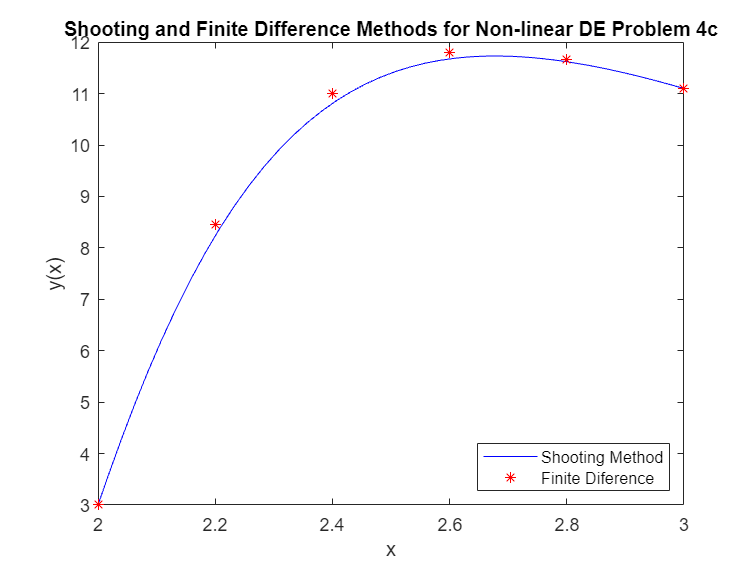

plot(x,y(:,1),'b',xfinite,yfinite,'r*')
xlabel 'x'
ylabel 'y(x)'
title 'Shooting and Finite Difference Methods for Non-linear DE Problem 4c'
legend('Shooting Method','Finite Diference','Location','southeast')

**d) Extra Credit (5 pts) Why is the shooting method plotted with a line and the finite difference method plotted just markers?**

The shoothing method produces a continuous function, so it is apropriate to graph it with a contiuious curve. On the other hand the finite difference method solves the system at specific points insted of a contuious range and thus must be graphed as discrete points.

## Helper functions

function dY = dydxNonlinear(x, Y)

dY = [Y(2);(-5-Y(2))*sqrt(Y(1))];

end


function r = shootingRes(za, x0, xf, y0, yf)

[~,y] = ode45(@dydxNonlinear, [x0 xf], [y0, za]);
r = y(end,1) - yf;
end

function y = yiter(y, dx)
% for from the second node to second to last
for index = 2:length(y)-1
    y(index) = (dx^2)/-2*(-y(index+1)/(dx^2)-y(index-1)/(dx^2)-5*sqrt(y(index))-sqrt(y(index))*(y(index+1)-y(index-1))/(2*dx));
end
end
